# RoadRunner - Path and vehicle speed tracking through Simulink cosimulation (utilizing Simscape Multibody)

## Clean up variables and RoadRunner

if exist("rrApp", "var")
    if class(rrApp) == "roadrunner"
        rrApp.close();
    end
end
if exist("rrSim", "var")
    delete(rrSim);
end
close all;
clear; 

## Launch RoadRunner from MATLAB

rrApp = roadrunner();

% Required scenario files, Copy behavior file
rrProjectPath = rrApp.status.Project.Filename;
copyfile("pathFollowingUtil/TrajectoryFollowBehavior14DoF.rrbehavior.rrmeta",fullfile(rrProjectPath,"Assets/Behaviors/"));
copyfile("pathFollowingUtil/slopeTest14DoF.rrscene", fullfile(rrProjectPath, "Scenes/"));
copyfile("pathFollowingUtil/slopeTest14DoF.rrscenario", fullfile(rrProjectPath, "Scenarios/"));

behaviorName = "TrajectoryFollowBehavior14DoF.rrbehavior";
% Start the scenario. The scene is linked to the scenario, so it will open automatically.
rrApp.openScenario("slopeTest14DoF");
rrApp.setScenarioVariable("EgoVehicleBehavior", "<PROJECT>/Assets/Behaviors/" + behaviorName); %Set behavior file

rrSim = rrApp.createSimulation();
rrSim.set("PacerStatus", "Off");
rrSim.set("MaxSimulationTime", 14);
set(rrSim,"Logging","on");

% Define a Bus object to obtain RoadRunner information in Simulink.
% To support Reader and Writer blocks, some bus objects must be loaded.
load(fullfile(matlabroot,'toolbox','driving','drivingdata','rrScenarioSimTypes.mat'));

addpath("pathFollowingUtil");
helperSLTrajectoryFollowerWithRRScenarioSetup(); %Set vehicle dynamics parameters and control parameters
% % Open Simulink model
model_name = 'TrajectoryFollowVehicleWith14DoF.slx';
open_system(model_name);


% Align the execution step size of RoadRunner and Simulink.
timeStep = 0.01;
RRtimeStep = 0.1;
rrSim.set("StepSize", RRtimeStep); 

## Move the vehicle according to the scenario trajectory

useDynamicsStanley = false; %Simulink model that moves according to the scenario trajectory
vehicleVariant = "3DOF";

% Get the vehicle initial values from RoadRunner and set them to the vehicle model.
helperSLTrajectoryFollowerWithRRScenarioSetup("rrAppObj", rrApp,...
    "scenarioSimulationObj", rrSim, "behaviorName", behaviorName);
% Start simulation
set(rrSim,"SimulationCommand","Start");
% Wait until RoadRunner Scenario simulation is finished.
while strcmp(get(rrSim,"SimulationStatus"),"Running")
    pause(1);
end

% Get log
rrLog = get(rrSim,"SimulationLog");

% Get vehicle speed
velocityAgent1 = get(rrLog,'Velocity','ActorID',1); % Get speed of Actor1
time1 = [velocityAgent1.Time];% Get time of Actor1

% Get vehicle movement
poseActor1 = rrLog.get('Pose','ActorID',1);
positionActor1_x = arrayfun(@(x) x.Pose(1,4),poseActor1);
positionActor1_y = arrayfun(@(x) x.Pose(2,4),poseActor1); 

## Utilize Simscape Multibody as a vehicle model

If the build fails, please see "For those experiencing execution/build errors" in handsOn06_simulaitonPathFollowing14DoF.mlx. 

useDynamicsStanley = true; %Simulink model that moves according to the scenario trajectory
vehicleVariant = "Multibody";

% Get the vehicle initial values from RoadRunner and set them to the vehicle model.
helperSLTrajectoryFollowerWithRRScenarioSetup("rrAppObj", rrApp,...
    "scenarioSimulationObj", rrSim, "behaviorName", behaviorName, MultibodySetting=true);

% Load terrain map created in advance
load("gridMap_groundHeight_RT.mat");

% Start simulation
set(rrSim,"SimulationCommand","Start");
% Wait until RoadRunner Scenario simulation is finished.
while strcmp(get(rrSim,"SimulationStatus"),"Running")
    pause(1);
end
% Get log
rrLog = get(rrSim,"SimulationLog");

% Get vehicle speed
velocityAgent4 = get(rrLog,'Velocity','ActorID',1); % Get speed of Actor1
time4 = [velocityAgent4.Time];% Get time of Actor1

% Get vehicle movement
poseActor4 = rrLog.get('Pose','ActorID',1);
positionActor4_x = arrayfun(@(x) x.Pose(1,4),poseActor4);
positionActor4_y = arrayfun(@(x) x.Pose(2,4),poseActor4); 

## Comparison plot

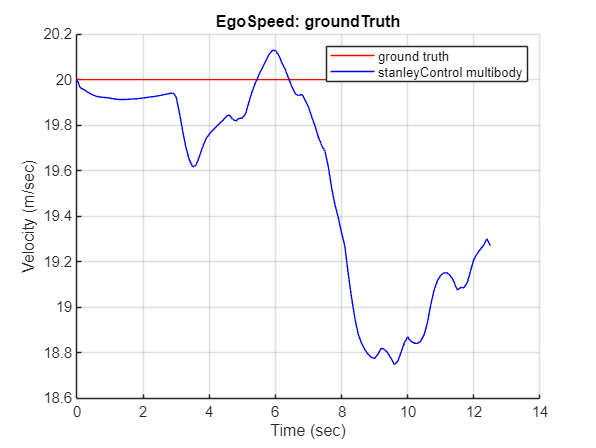

figure;
helperPlotVelocity(time1, velocityAgent1, time4, velocityAgent4);
title("EgoSpeed: groundTruth");

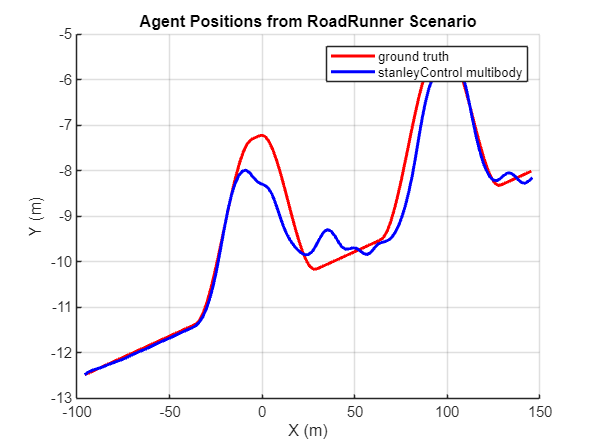


helperPlotTrajectory(positionActor1_x, positionActor1_y, positionActor4_x, positionActor4_y); 

function helperPlotVelocity(time1, velocityAgent1, time2, velocityAgent2)
    velMagAgent1 = arrayfun(@(x) norm(x.Velocity,2),velocityAgent1);
    velMagAgent2 = arrayfun(@(x) norm(x.Velocity,2),velocityAgent2);


    % Plot the agent velocities with respect to simulation time using the plot function. Label the graph and the x and y axes.
    figure
    hold on
    plot(time1,velMagAgent1,"r")
    plot(time2,velMagAgent2,"b")
    grid on
    title("Agent Velocities from RoadRunner Scenario")
    ylabel("Velocity (m/sec)")
    xlabel("Time (sec)")
    legend("ground truth", "stanleyControl multibody")
end
function helperPlotTrajectory(positionActor1_x, positionActor1_y, positionActor2_x, positionActor2_y)
    % hdMap = getMap(rrSim);
    % lanes = hdMap.map.lanes;
    % Loop through each of the lane specifications using a for loop and plot the lane coordinates.
    
    figure
    hold on

    plot(positionActor1_x,positionActor1_y,"r","LineWidth",2);
    hold on;
    plot(positionActor2_x,positionActor2_y,"b","LineWidth",2);
    legend("ground truth", "stanleyControl multibody")
    title("Agent Positions from RoadRunner Scenario");
    ylabel("Y (m)");
    xlabel("X (m)");
    grid on;
end